# derive_equations_JR.m

Description: Symbolically derive equations related to the jumping robot, including the full nonlinear state-space dynamics.

Inputs: none

Outputs: none

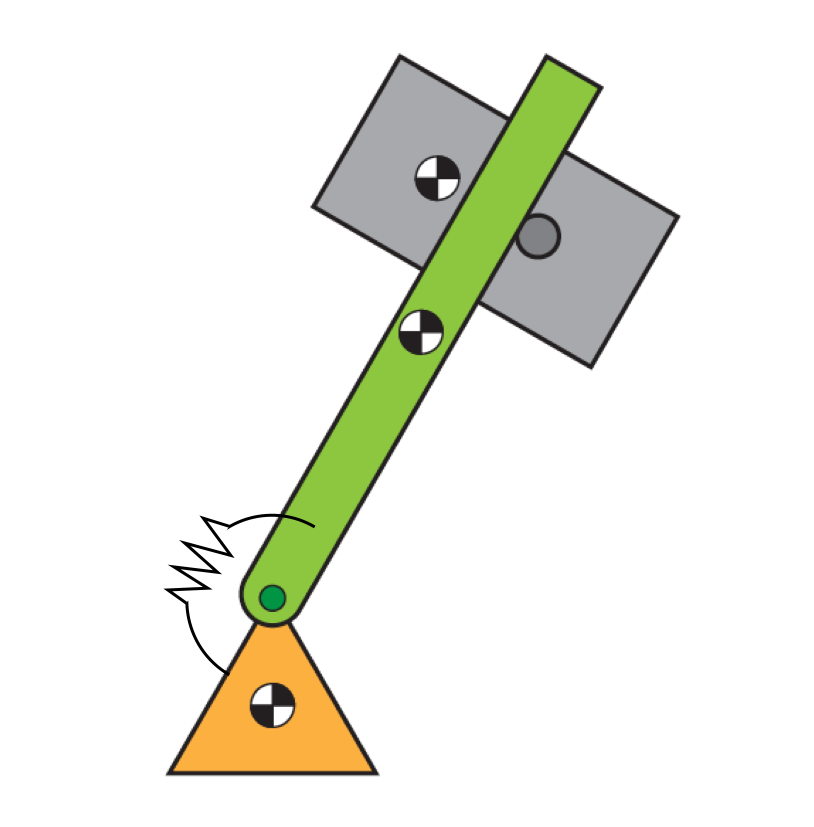

% Script Version:  derive_equations_JR_script.mxl
clear;
close all;
clc;

fprintf('Deriving jumping robot equations...\n');

Deriving jumping robot equations...


## Variable definition

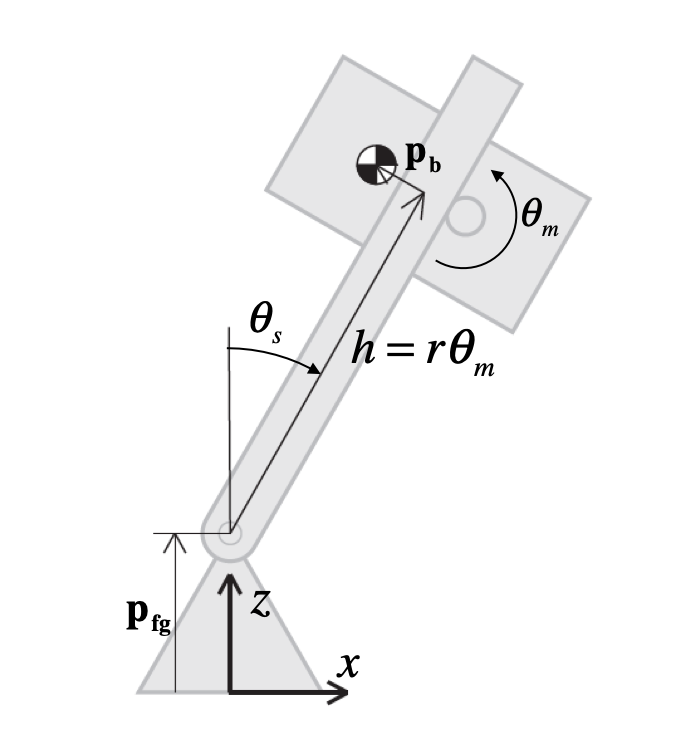 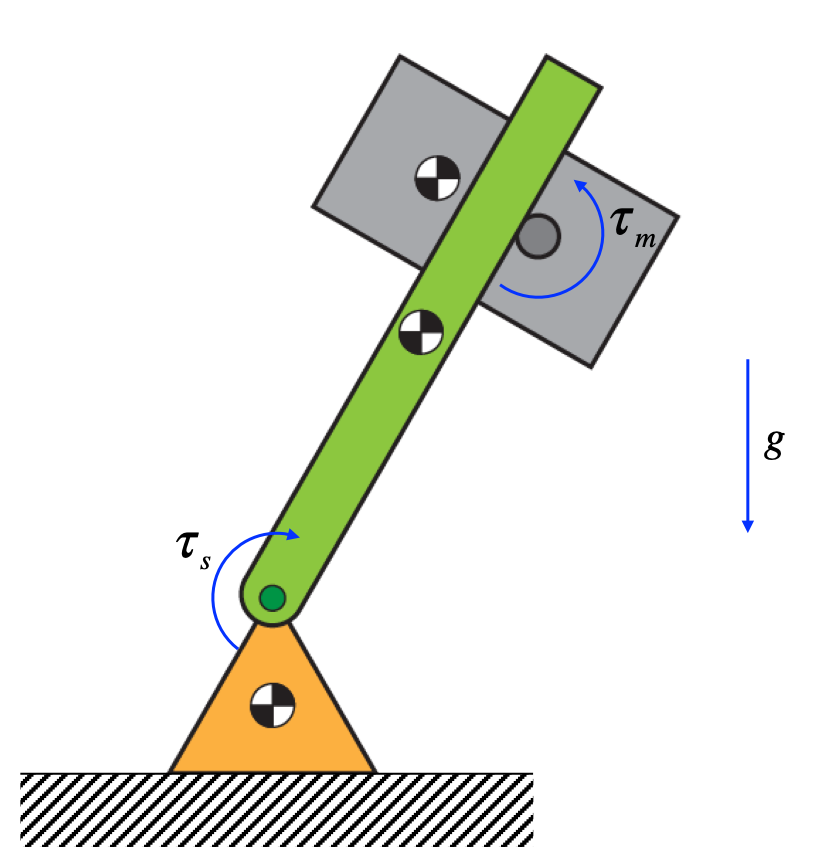

fprintf('\tInitializing generalized coordinates, velocities, accelerations, and forces...\n');

	Initializing generalized coordinates, velocities, accelerations, and forces...



% Generalized coordinates:
% theta_s: angle of the spine relative to vertical; positive cw
% theta_m: angle of the motor; positive ccw
syms theta_s theta_m real
q = [theta_s; theta_m];

% Generalized velocities:
% dtheta_s: angular velocity of the spine
% dtheta_m: angular velocity of the motor
syms dtheta_s dtheta_m real
dq = [dtheta_s; dtheta_m];

% Generalized accelerations:
syms ddtheta_s ddtheta_m real
% ddtheta_s: angular acceleration of the spine
% ddtheta_m: angular acceleration of the spine
ddq = [ddtheta_s; ddtheta_m];

% Generalized forces:
% tau_s: torque at base of spine; positive cw
% tau_m: motor torque on body motor; positive ccw
syms tau_s tau_m real 
Q = [tau_s; tau_m];

fprintf('\t...done.\n');

	...done.


## Inertial (and other) parameters

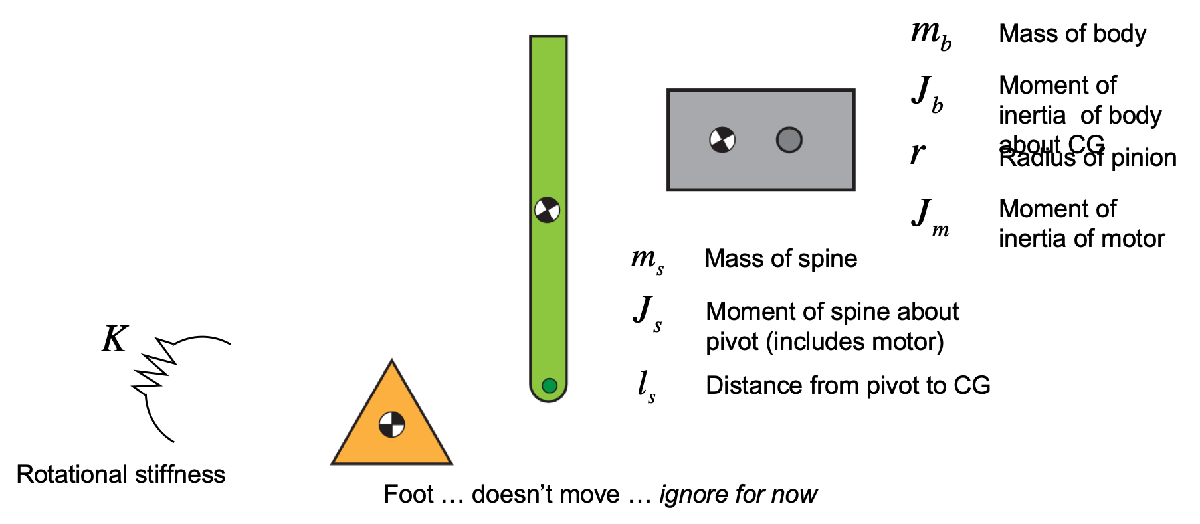

fprintf('\tInitializing inertial (and other) parameters...\n');

	Initializing inertial (and other) parameters...



% Mass of each body:
syms m_s m_b real

% Rotational inertia of each component:
syms J_pivot_s J_com_b J_m real

% Stiffness between sping and foot:
syms K real

% Geometry:
syms l_s p_b p_fg r real

% Other variables
g = sym('g','real'); % gravity
% t = sym('t','real'); % time

fprintf('\t...done.\n');

	...done.


## Forward Kinematics

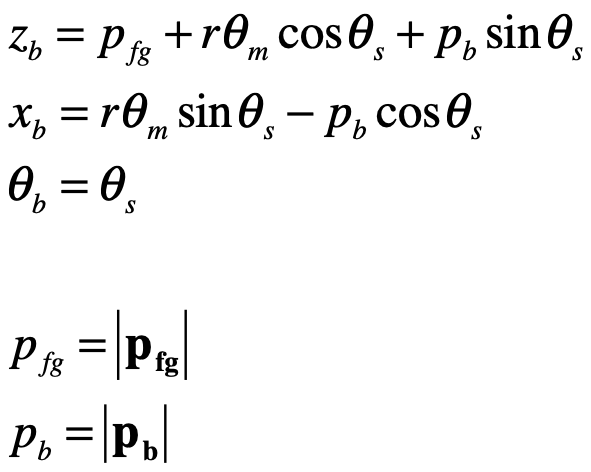

fprintf('\tInitializing kinematics variables...\n');

	Initializing kinematics variables...



% x and z coordinates of the body CoM:
syms x_com_b z_com_b real

% x and z coordinates of the spine tip:
% syms x_tip_s z_tip_s real
% Note: the dynamics don't care where the spine tip is (only the 
% spine CoM), but keeping track of the tip will be helpful for 
% visualizing the robot (could also be helpful for some control tasks).
fprintf('\t...done.\n');

	...done.


fprintf('\tGenerating forward kinematics equations...\n');

	Generating forward kinematics equations...



x_com_b = r*theta_m*sin(theta_s) - p_b*cos(theta_s);
z_com_b = p_fg + r*theta_m*cos(theta_s) + p_b*sin(theta_s);


% create a 2x1 array to hold all forward kinematics (FK) outputs:
FK = [x_com_b;
      z_com_b];

% generate a MATLAB function to compute all the FK outputs:
matlabFunction(FK,'File','autogen_fwd_kin');
% Note: this autogenerated function will make plotting/animation easier
% later. Could also help with some control tasks.
fprintf('\t...done.\n');

	...done.


## Derivatives

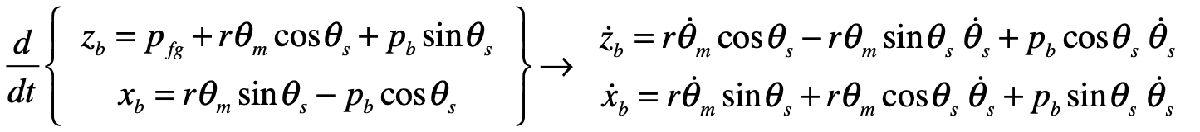

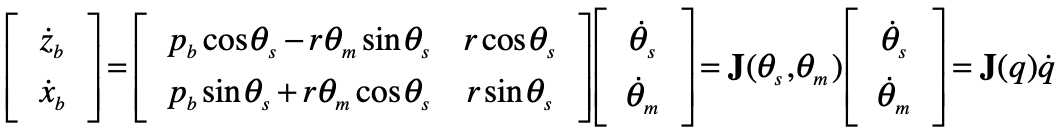

fprintf('\tGenerating time derivatives of the kinematics equations...\n');

	Generating time derivatives of the kinematics equations...



% Body CoM velocities:
syms dFK real
% dFK: time derivative of translational motion of body CoM

dFK = jacobian(FK,q)*dq

$$dFK = \left(\begin{array}{c} {\mathrm{dtheta}}_{s}\,\left(p_{b}\,\sin\left(\theta_{s}\right)+r\,\theta_{m}\,\cos\left(\theta_{s}\right)\right)+{\mathrm{dtheta}}_{m}\,r\,\sin\left(\theta_{s}\right)\\ {\mathrm{dtheta}}_{s}\,\left(p_{b}\,\cos\left(\theta_{s}\right)-r\,\theta_{m}\,\sin\left(\theta_{s}\right)\right)+{\mathrm{dtheta}}_{m}\,r\,\cos\left(\theta_{s}\right) \end{array}\right)$$

fprintf('\t...done.\n');

	...done.


## Kinetic energy

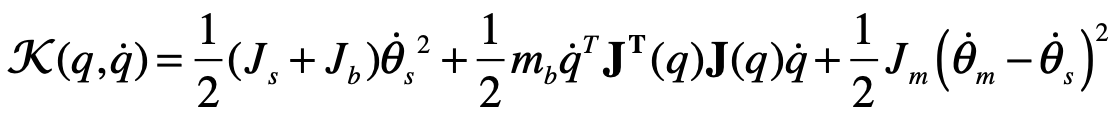

fprintf('\tGenerating kinetic energy equation...\n');

	Generating kinetic energy equation...



syms ke_s ke_b KE real

% kinetic energy of each body:
ke_s = 0.5*J_pivot_s*dtheta_s^2;
ke_b = 0.5*J_com_b*dtheta_s^2 + 0.5*m_b*(dFK'*dFK) + 0.5*J_m*(dtheta_m - dtheta_s)^2;

% total kinetic energy:
KE = ke_s + ke_b

$$KE = \frac{J_{\mathrm{com},b}\,{{\mathrm{dtheta}}_{s}}^{2}}{2}+\frac{J_{\mathrm{pivot},s}\,{{\mathrm{dtheta}}_{s}}^{2}}{2}+\frac{J_{m}\,{\left({\mathrm{dtheta}}_{m}-{\mathrm{dtheta}}_{s}\right)}^{2}}{2}+\frac{m_{b}\,{\left({\mathrm{dtheta}}_{s}\,\left(p_{b}\,\cos\left(\theta_{s}\right)-r\,\theta_{m}\,\sin\left(\theta_{s}\right)\right)+{\mathrm{dtheta}}_{m}\,r\,\cos\left(\theta_{s}\right)\right)}^{2}}{2}+\frac{m_{b}\,{\left({\mathrm{dtheta}}_{s}\,\left(p_{b}\,\sin\left(\theta_{s}\right)+r\,\theta_{m}\,\cos\left(\theta_{s}\right)\right)+{\mathrm{dtheta}}_{m}\,r\,\sin\left(\theta_{s}\right)\right)}^{2}}{2}$$


fprintf('\t...done.\n');

	...done.


## Potential energy

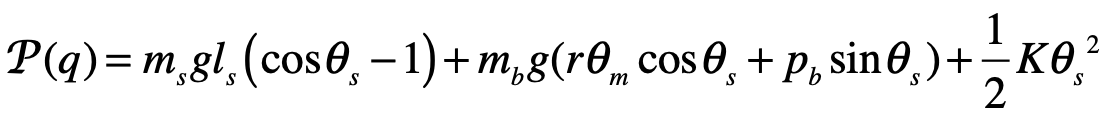

fprintf('\tGenerating potential energy equation...\n');

	Generating potential energy equation...



syms pe_s pe_b real

% potential energy of each body:
pe_s = m_s*g*l_s*(cos(theta_s - 1)) + 0.5*K*theta_s^2;
pe_b = m_b*g*(r*theta_m*cos(theta_s) + p_b*sin(theta_s));

% total potential energy:
PE = pe_s + pe_b

$$PE = \frac{K\,{\theta_{s}}^{2}}{2}+g\,m_{b}\,\left(p_{b}\,\sin\left(\theta_{s}\right)+r\,\theta_{m}\,\cos\left(\theta_{s}\right)\right)+g\,l_{s}\,m_{s}\,\cos\left(\theta_{s}-1\right)$$


fprintf('\t...done.\n');

	...done.


## Lagrangian

fprintf('\tGenerating Lagrangian...\n');

	Generating Lagrangian...



syms L real
L = KE - PE;

fprintf('\t...done.\n');

	...done.


## Euler-Lagrange equations

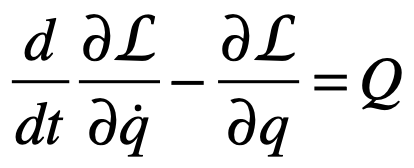

fprintf('\tGenerating Euler-Lagrange equations of motion...\n')

	Generating Euler-Lagrange equations of motion...



% Variable initializations:
del_L_del_dq = sym('del_L_del_dq',[numel(q),1],'real'); % del L/del dq
ELeq_term1  = sym('ELeq_term1',[numel(q),1],'real'); % d(del L/del dq)/dt
ELeq_term2  = sym('ELeq_term2',[numel(q),1],'real'); % del L/del q

del_L_del_dq = jacobian(L,dq)';
ELeq_term1 = simplify(jacobian(del_L_del_dq,[q;dq])*[dq;ddq])

$$ELeq\_term1 = \left(\begin{array}{c} {\mathrm{ddtheta}}_{s}\,m_{b}\,{p_{b}}^{2}+{\mathrm{ddtheta}}_{m}\,m_{b}\,p_{b}\,r+{\mathrm{ddtheta}}_{s}\,m_{b}\,r^{2}\,{\theta_{m}}^{2}+2\,{\mathrm{dtheta}}_{m}\,{\mathrm{dtheta}}_{s}\,m_{b}\,r^{2}\,\theta_{m}+J_{\mathrm{com},b}\,{\mathrm{ddtheta}}_{s}-J_{m}\,{\mathrm{ddtheta}}_{m}+J_{m}\,{\mathrm{ddtheta}}_{s}+J_{\mathrm{pivot},s}\,{\mathrm{ddtheta}}_{s}\\ {\mathrm{ddtheta}}_{m}\,m_{b}\,r^{2}+{\mathrm{ddtheta}}_{s}\,m_{b}\,p_{b}\,r+J_{m}\,{\mathrm{ddtheta}}_{m}-J_{m}\,{\mathrm{ddtheta}}_{s} \end{array}\right)$$

ELeq_term2 = simplify(jacobian(L,q))'

$$ELeq\_term2 = \left(\begin{array}{c} g\,l_{s}\,m_{s}\,\sin\left(\theta_{s}-1\right)-g\,m_{b}\,\left(p_{b}\,\cos\left(\theta_{s}\right)-r\,\theta_{m}\,\sin\left(\theta_{s}\right)\right)-K\,\theta_{s}\\ -m_{b}\,r\,\left(g\,\cos\left(\theta_{s}\right)-{{\mathrm{dtheta}}_{s}}^{2}\,r\,\theta_{m}\right) \end{array}\right)$$


fprintf('\t...done.\n')

	...done.


## Finding the mass matrix

fprintf('\tSolving for the mass matrix...\n');

	Solving for the mass matrix...



% Note: the highest order derivative that shows up in the Euler-Lagrange
% Equations is second:  ddq  (accelerations)
% Our goal is to obtain equations for ddq in terms of the state q, state
% derivatives dq, and generalized forces (i.e., the motor torques) Q.  
% These equations can then be integrated forward in time.  
% Fortunately, the accelerations always show up linearly and the matrix
% that multiplies them, the "mass matrix" is guaranteed to be invertible:
%       M(q)*ddq + H(q,dq) = Q
% Note that this equation is a generalization of F=ma. It represents the *inverse* dynamics, 
% mapping positions, velocities, and accelerations of the joints to forces
% or torques (depending on the nature of each joint).

% Important note:  there is additional structure in H that is often
% important to know about.  We won't go into that here.

M = sym('M',[numel(q),numel(q)],'real');
H = sym('H',[numel(q),1],'real');

M = simplify(jacobian(del_L_del_dq,dq))

$$M = \left(\begin{array}{cc} m_{b}\,{p_{b}}^{2}+m_{b}\,r^{2}\,{\theta_{m}}^{2}+J_{\mathrm{com},b}+J_{m}+J_{\mathrm{pivot},s} & m_{b}\,p_{b}\,r-J_{m}\\ m_{b}\,p_{b}\,r-J_{m} & m_{b}\,r^{2}+J_{m} \end{array}\right)$$

H = simplify(jacobian(del_L_del_dq,q)*dq - ELeq_term2)

$$H = \left(\begin{array}{c} 2\,{\mathrm{dtheta}}_{m}\,{\mathrm{dtheta}}_{s}\,m_{b}\,\theta_{m}\,r^{2}-g\,m_{b}\,\theta_{m}\,\sin\left(\theta_{s}\right)\,r+K\,\theta_{s}+g\,m_{b}\,p_{b}\,\cos\left(\theta_{s}\right)-g\,l_{s}\,m_{s}\,\sin\left(\theta_{s}-1\right)\\ m_{b}\,r\,\left(g\,\cos\left(\theta_{s}\right)-{{\mathrm{dtheta}}_{s}}^{2}\,r\,\theta_{m}\right) \end{array}\right)$$


fprintf('\t\t...done building M and H.\n');

		...done building M and H.



% Note: we need inv(M) to compute the fwd. dynamics and therefore the 
% state-space dynamics (see below), so to ease computation cost we derive 
% inv(M) symbolically here and autogenerate a dedicated MATLAB function for 
% evaluating it.

% compute and store inv(M):
fprintf('\t\tComputing inv(M)...\n')

		Computing inv(M)...


Minv = sym('Minv',[numel(q),numel(q)],'real');
Minv = simplify(inv(M))

$$Minv = \begin{array}{l} \left(\begin{array}{cc} \frac{m_{b}\,r^{2}+J_{m}}{\sigma_{1}} & \frac{J_{m}-m_{b}\,p_{b}\,r}{\sigma_{1}}\\ \frac{J_{m}-m_{b}\,p_{b}\,r}{\sigma_{1}} & \frac{m_{b}\,{p_{b}}^{2}+m_{b}\,r^{2}\,{\theta_{m}}^{2}+J_{\mathrm{com},b}+J_{m}+J_{\mathrm{pivot},s}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=J_{\mathrm{com},b}\,J_{m}+J_{m}\,J_{\mathrm{pivot},s}+{m_{b}}^{2}\,r^{4}\,{\theta_{m}}^{2}+J_{m}\,m_{b}\,{p_{b}}^{2}+J_{\mathrm{com},b}\,m_{b}\,r^{2}+J_{m}\,m_{b}\,r^{2}+J_{\mathrm{pivot},s}\,m_{b}\,r^{2}+J_{m}\,m_{b}\,r^{2}\,{\theta_{m}}^{2}+2\,J_{m}\,m_{b}\,p_{b}\,r \end{array}$$

fprintf('\t\t...done.\n')

		...done.



fprintf('\t\tGenerating MATLAB functions...\n');

		Generating MATLAB functions...


matlabFunction(M,'File','autogen_mass_matrix');
matlabFunction(Minv,'File','autogen_inverse_mass_matrix');
matlabFunction(H,'File','autogen_H');
fprintf('\t\t...done.\n');

		...done.



fprintf('\t...done putting Euler-Lagrange equations into manipulator form.\n');

	...done putting Euler-Lagrange equations into manipulator form.


## Generate (nonlinear) state-space model from manipulator equation

fprintf('\tConverting manipulator equation to state-space form...\n');

	Converting manipulator equation to state-space form...



% Note: building the state-space dynamics from the manipulator equation has
% two steps:
% 
%   1) the manipulator equation gives the *inverse* dynamics (mapping from
%   state and accelerations to forces/torques). We need
%   the *forward* dynamics (mapping from state and forces/torques to
%   accelerations), so we must solve the manipulator equation for ddq:
% 
%       ddq = Minv*(Q - H);
% 
%   2) Solving the manipular equation for ddq gives us the forward
%   dynamics, represented as a system of 2nd-order ODEs. The state-space
%   dynamics are represented as a system of 1st-order ODEs, so we must
%   convert the 2nd-order system to a 1st-order system:
% 
%       x   = [q;  dq]; % state vector
%       dx  = [dq; ddq]; % derivative of the state vector w.r.t. time
% 
%       % Substitute the forward dynamics for ddq in the equation for dx,
%       resulting in a system of 4 1st-order ODEs:
% 
%       dx = [dq; Minv*(Q - H)];

ddq = Minv*(Q - H)

$$ddq = \begin{array}{l} \left(\begin{array}{c} \frac{\sigma_{3}\,\left(J_{m}-m_{b}\,p_{b}\,r\right)}{\sigma_{1}}+\frac{\left(m_{b}\,r^{2}+J_{m}\right)\,\sigma_{2}}{\sigma_{1}}\\ \frac{\sigma_{3}\,\left(m_{b}\,{p_{b}}^{2}+m_{b}\,r^{2}\,{\theta_{m}}^{2}+J_{\mathrm{com},b}+J_{m}+J_{\mathrm{pivot},s}\right)}{\sigma_{1}}+\frac{\left(J_{m}-m_{b}\,p_{b}\,r\right)\,\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=J_{\mathrm{com},b}\,J_{m}+J_{m}\,J_{\mathrm{pivot},s}+{m_{b}}^{2}\,r^{4}\,{\theta_{m}}^{2}+J_{m}\,m_{b}\,{p_{b}}^{2}+J_{\mathrm{com},b}\,m_{b}\,r^{2}+J_{m}\,m_{b}\,r^{2}+J_{\mathrm{pivot},s}\,m_{b}\,r^{2}+J_{m}\,m_{b}\,r^{2}\,{\theta_{m}}^{2}+2\,J_{m}\,m_{b}\,p_{b}\,r\\ \sigma_{2}=-2\,{\mathrm{dtheta}}_{m}\,{\mathrm{dtheta}}_{s}\,m_{b}\,\theta_{m}\,r^{2}+g\,m_{b}\,\theta_{m}\,\sin\left(\theta_{s}\right)\,r+\tau_{s}-K\,\theta_{s}-g\,m_{b}\,p_{b}\,\cos\left(\theta_{s}\right)+g\,l_{s}\,m_{s}\,\sin\left(\theta_{s}-1\right)\\ \sigma_{3}=\tau_{m}-m_{b}\,r\,\left(g\,\cos\left(\theta_{s}\right)-{{\mathrm{dtheta}}_{s}}^{2}\,r\,\theta_{m}\right) \end{array}$$


fprintf('\t...done converting manipulator equation to state-space form.\n');

	...done converting manipulator equation to state-space form.


## Create a Simulink Block 

new_system('Jumping_Robot_system')
open_system('Jumping_Robot_system')

input_variable_order = {'g', 'm_s', 'm_b', 'J_pivot_s', 'J_com_b', 'J_m', ...
    'K', 'l_s', 'p_b', 'r', 'theta_s', 'theta_m', 'dtheta_s', 'dtheta_m', ...
    'tau_s', 'tau_m'};

matlabFunctionBlock('Jumping_Robot_system/Robot_dynamics',ddq(1),ddq(2),'Vars',input_variable_order,'Outputs',{'ddtheta_s', 'ddtheta_m'})

fprintf('\t...done creating Simulink Block.\n');

	...done creating Simulink Block.


## Done!

fprintf('...done deriving cart-pendulum equations.\n');

...done deriving cart-pendulum equations.
